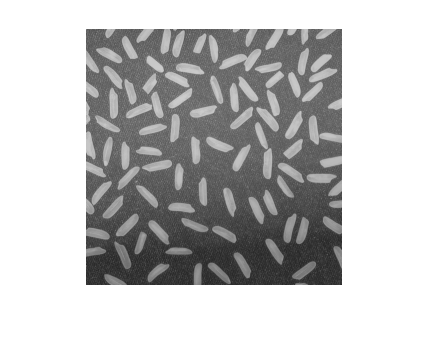

I = imread('rice.png');
imshow(I);

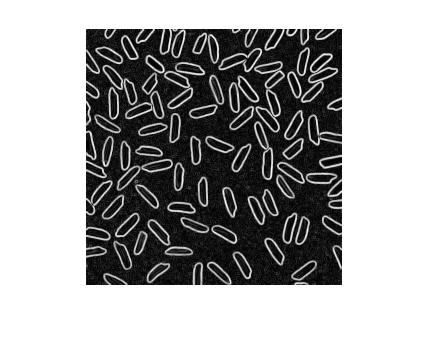


G = imgradient(I);
G = (G - min(min(G))) / max(max(G));
imshow(G);

% Process
th = 0:.001:1;
fs = 1:2:10;
A = zeros(numel(th), numel(fs));
n = 1e3;
l = zeros([numel(th), numel(fs), n]);

for ith = 1:numel(th)
    for ifs = 1:numel(fs)
        [A(ith, ifs), l(ith, ifs, :)] = process(G, th(ith), fs(ifs), n);
    end
end

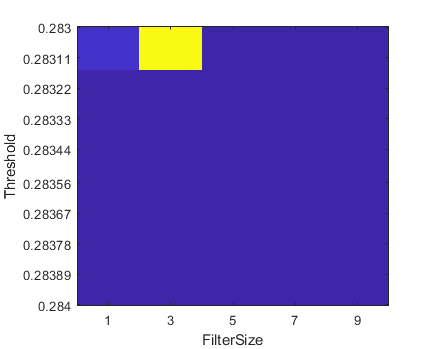

% Results
imagesc(A);

tth = round(linspace(1,numel(th),min(10,numel(th))));
yticks(tth);
yticklabels(th(tth));
ylabel('Threshold');

tfs = round(linspace(1,numel(fs),min(10,numel(fs))));
xticks(tfs);
xticklabels(fs(tfs));
xlabel('FilterSize');

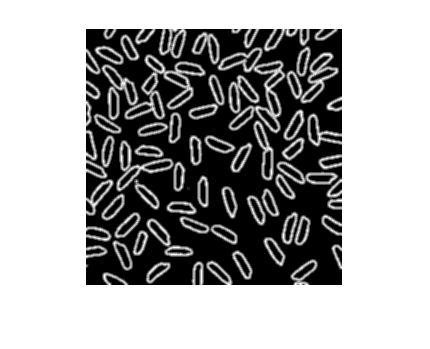

% Pick
[~,~,G2] = process(G, .283, 3, 2);
imshow(G2,[]);

function [i, l, G] = process(G, th, fs, n)
    l = zeros(1,n);
    l(1) = mean(mean(G));
    
    for i = 2:n
        G = double(G > th);
        G = imboxfilt(G,fs);
        l(i) = mean(mean(G));
        dl = l(i) - l(i-1);
        if abs(dl) < .01
            break
        end
    end
%     plot(l(1:i))
end